# Versuchsprotokoll von Gruppe 17

## Mitglieder:

- Zican Huang - 417592

- Yating Liu - 424624

- Hongli Mao - 417595

- Qigang Wang - 415152

# Lösung

## Aufgabe 1

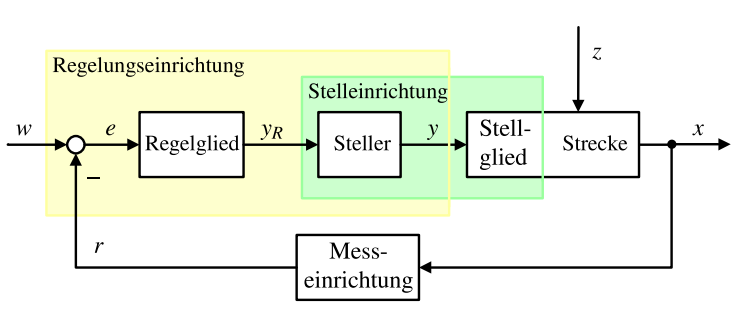

- **Störgröße**: externe Weganregung Z_r

- **Stellgröße**: Aktorkraft F_a 

- **Regelgröße**: Auslenkung Z_s

## Aufgabe 2

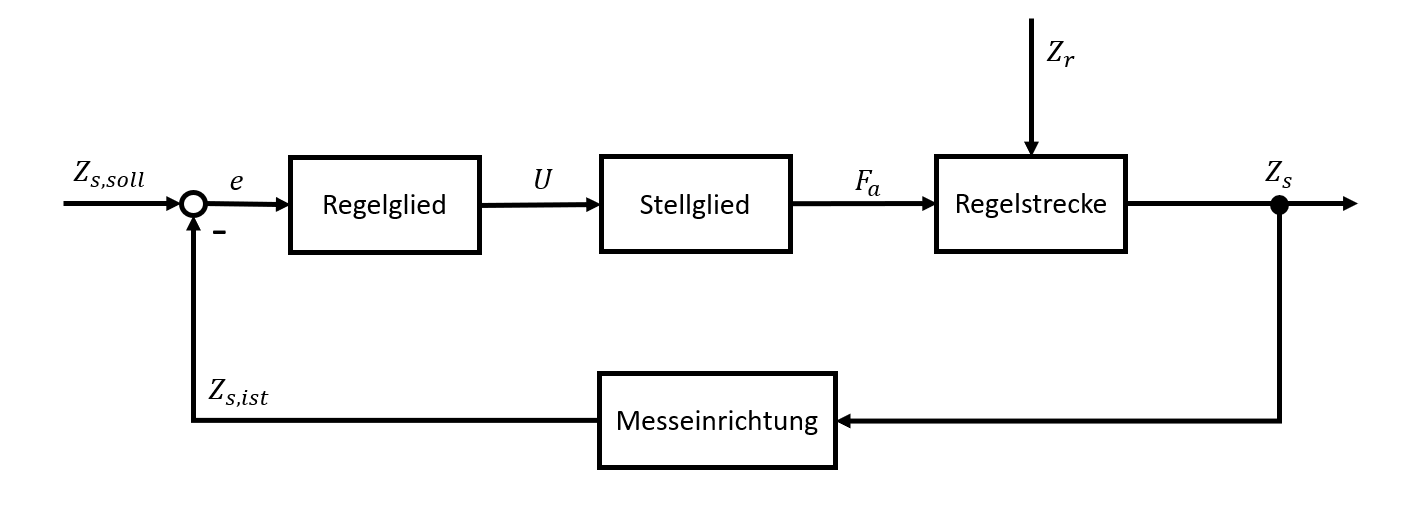

Regelglied und Stellglied werden zusmmengefasst.

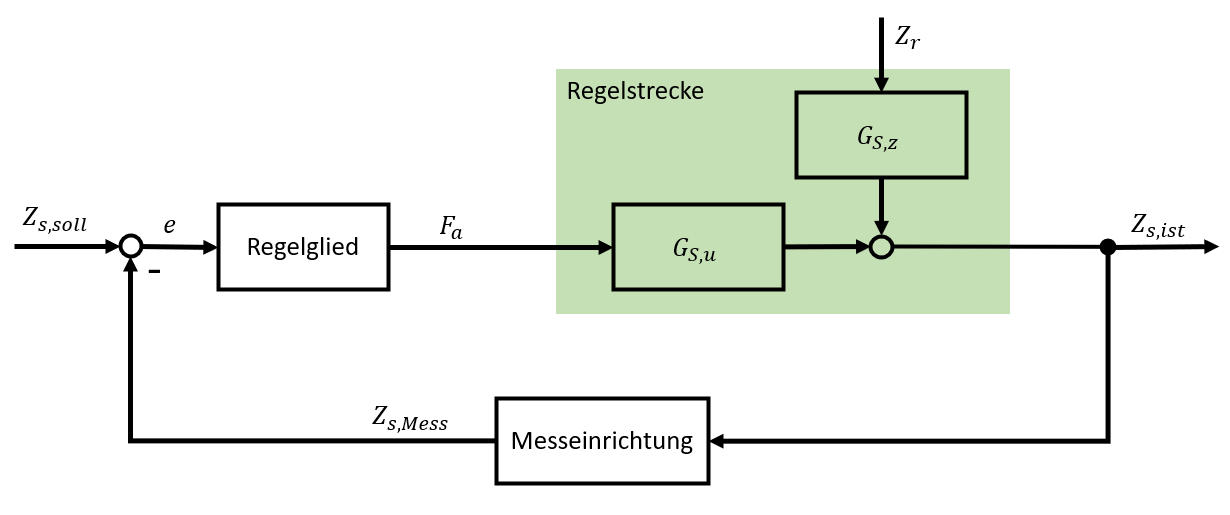

## Aufgabe 3

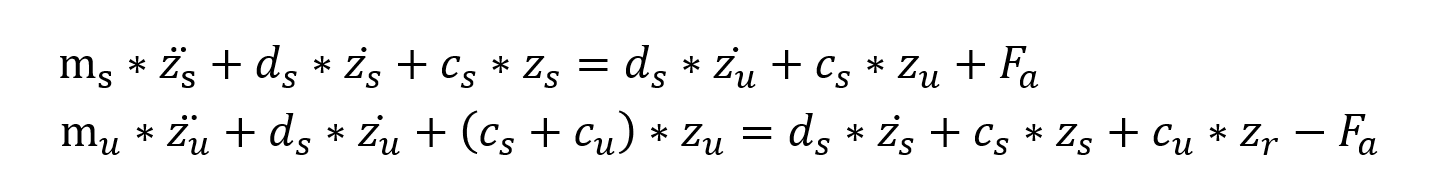

## Aufgabe 4

# Kann folgndes Bild als Wirkungsplan betrachtet werden?

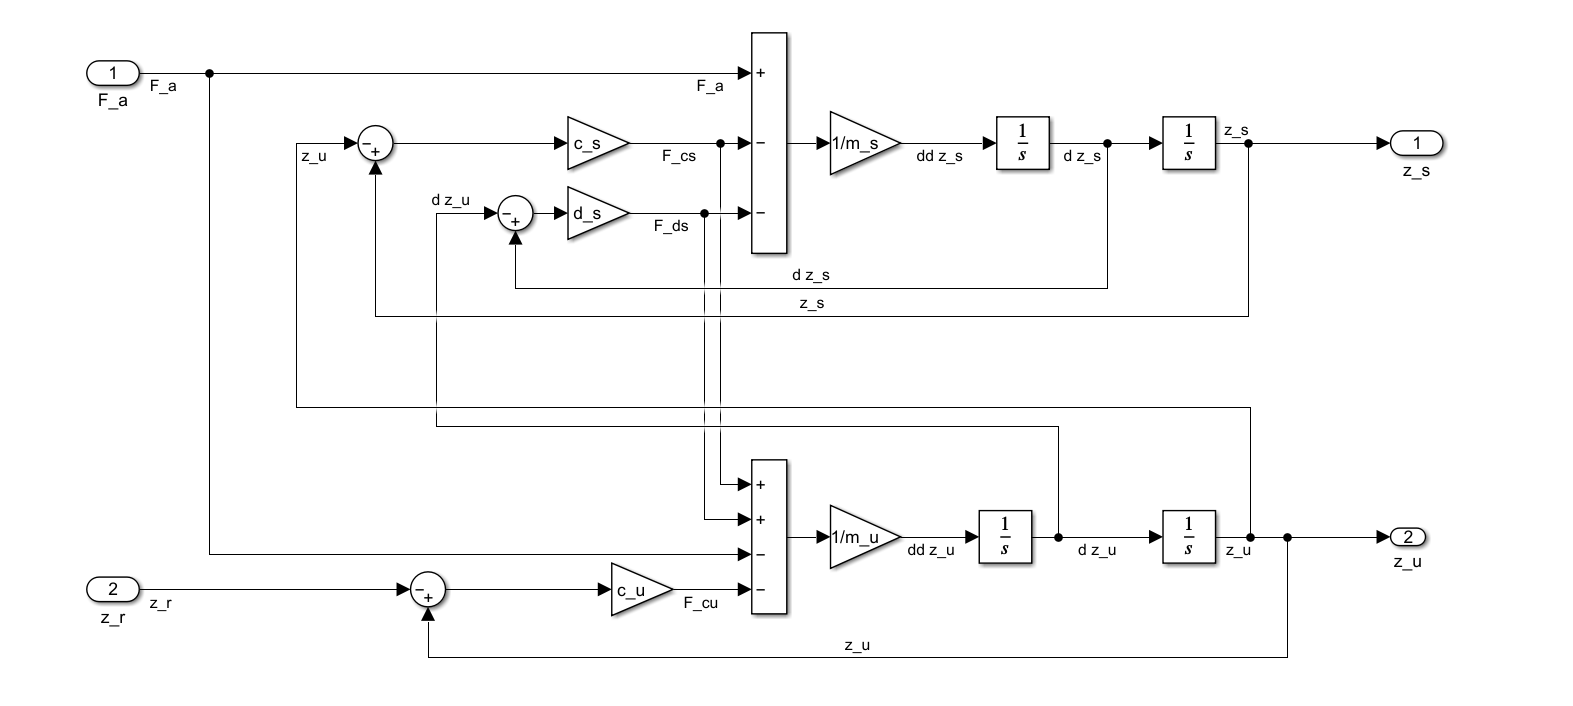

## Aufgabe 5

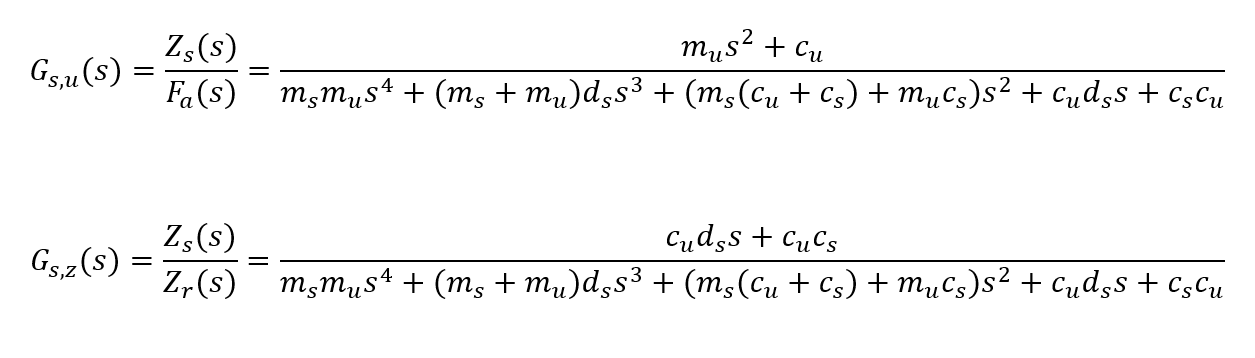

## Aufgabe 6

Das Modell wird im der Vorlage Aufgabe_6_Vorlage_mdl umgesetzt. Das Ergebnis ist richtig.

Aufgabe_6_Vorlage

## Aufagbe 7

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% IRT Regelunsgtechnisches Labor
% Aufgabe 7 und 8 - Vorlage
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clc
clear
close all

% Parameter der Regelstrecke Viertelfahrzeug

% Massen
m_s = 4.5;             % Aufbaumasse [kg]
m_u = 0.9;             % Radmasse [kg]

% Federsteifigkeiten
c_s = 177;             % Federsteifigkeit c_s [N/m]
c_u = 885;             % Federsteifigkeit c_u [N/m]

% Dämpferkonstanten
d_s = 0.142*10^3*0.1;  % Dämpferkonstante d_s [Ns/m]


%% Teilübertragungsfunktion aufstellen

% Koeffizienten des Zählerpolynoms
b2_u = m_u;
b1_u = 0;
b0_u = c_u;

% Koeffizienten des Nennerpolynoms
a4_u = m_u*m_s;
a3_u = (m_u+m_s)*d_s;
a2_u = m_s*(c_s+c_u)+m_u*c_s;
a1_u = d_s*c_u;
a0_u = c_s*c_u;

Gsu = tf([b2_u,b1_u,b0_u],[a4_u,a3_u,a2_u,a1_u,a0_u]);

### **Ohne Regler:**

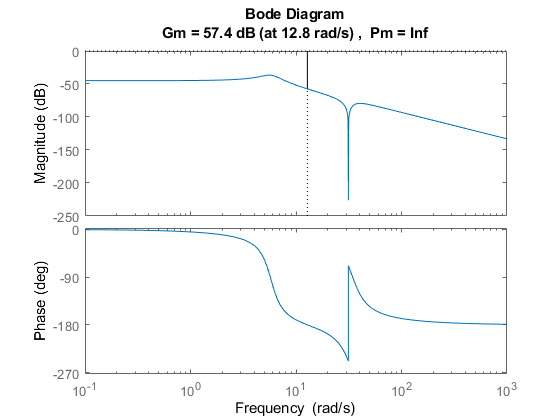

margin(Gsu)

G_Ohne_Regler = feedback(Gsu,1)

G0_Ohne_Regler =
 
                      0.9 s^2 + 885
  -----------------------------------------------------
  4.05 s^4 + 76.68 s^3 + 4939 s^2 + 1.257e04 s + 157530
 
Continuous-time transfer function.



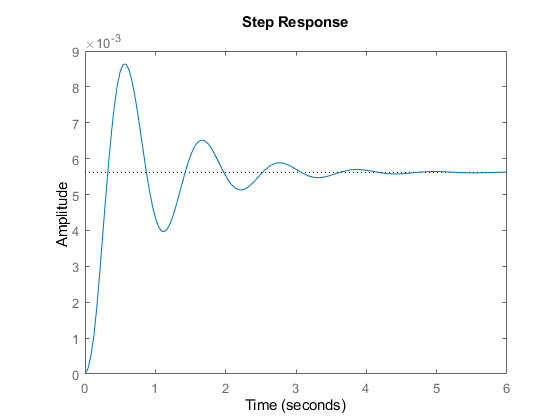

step(G_Ohne_Regler)

*Einschwingtoleranz = 2%*

Ohne Regler: C *= 1*

- Überschwingweite: 53,7%

- Anschwingzeit: 0,32s

- Einschwingzeit: 3,44s

- Bleibender Regelabweichung: (1-0,00562)/1 *= 99,438%*

### Mit P-Regler:

%% Reglerauslegung

% P-Regler
Gr_P = 1;

% Offenen Regelkreis aufstellen
G0P = Gsu*Gr_P;
% Bode Plot für offenen Regelkreis
margin(G0P);

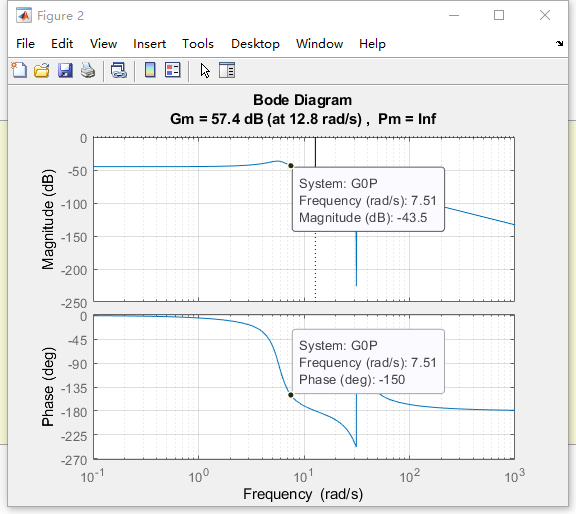

% Reglerauslegung ergänzen
% Aufagbe 7
G0P = Gsu*db2mag(43.5)

G0P =
 
                  134.7 s^2 + 1.324e05
  -----------------------------------------------------
  4.05 s^4 + 76.68 s^3 + 4938 s^2 + 1.257e04 s + 156645
 
Continuous-time transfer function.



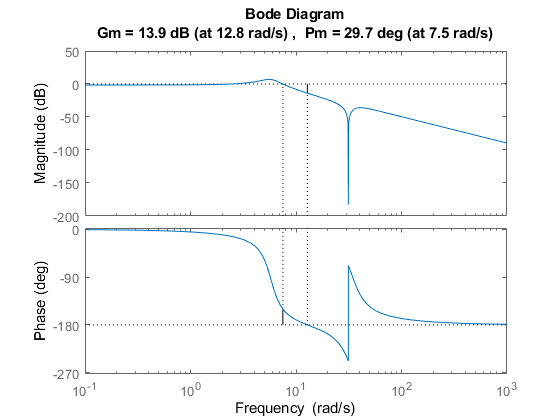

margin(G0P)

G_P_Regler = feedback(G0P,1)

G_P_Regler =
 
                   134.7 s^2 + 1.324e05
  -------------------------------------------------------
  4.05 s^4 + 76.68 s^3 + 5073 s^2 + 1.257e04 s + 2.891e05
 
Continuous-time transfer function.



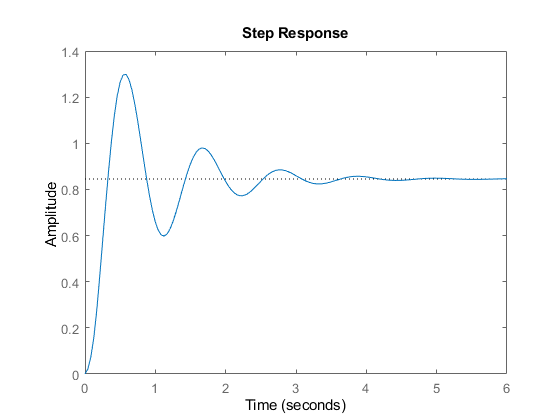

step(G0P)

Mit P-Regler: C *= 148.37*

- Überschwingweite: 68,1%

- Anschwingzeit: 0,23s

- Einschwingzeit: 4,16s

- Bleibender Regelabweichung: 1-0,456 = 0,544

P Regler ist nicht geeignet zur Regelung des Viertelfahrzeugs, weil es immer noch Reglerabweichung gibt.

### Mit I-Regler

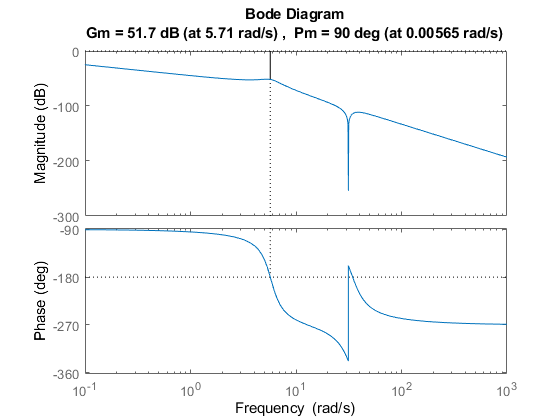

s = tf('s');
% PI-Regler
Gr_I = 1/s;

% Offenen Regelkreis aufstellen
G0I = Gsu*Gr_I;
% Bode Plot für offenen Regelkreis
margin(G0I);

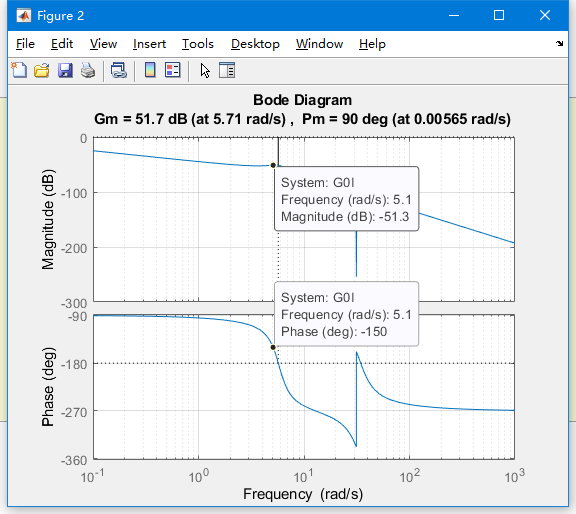

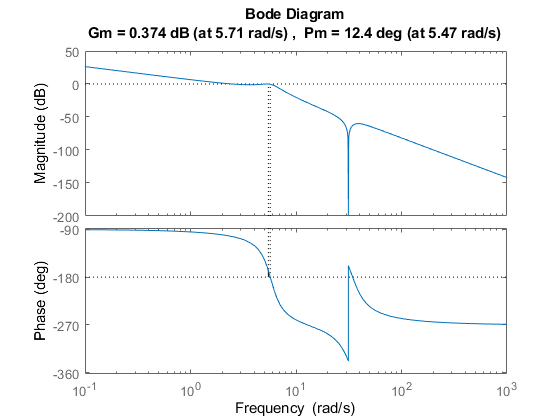

G0I = Gsu*db2mag(51.3)/s;
margin(G0I)

sisotool(G0I)
G_I_Regler = feedback(G0I,1)

G_I_Regler =
 
                         330.6 s^2 + 3.25e05
  ------------------------------------------------------------------
  4.05 s^5 + 76.68 s^4 + 4938 s^3 + 1.29e04 s^2 + 156645 s + 3.25e05
 
Continuous-time transfer function.



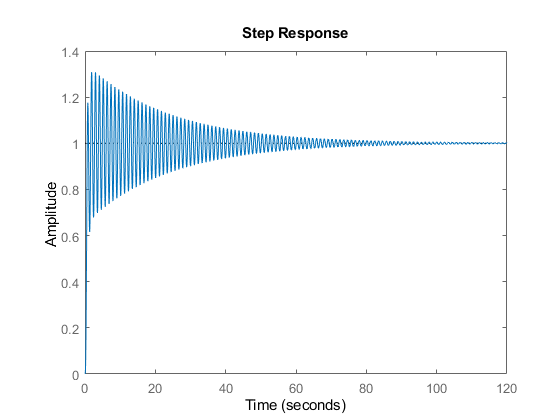

step(G_I_Regler)

Mit I-Regler: Es ist unmöglich, eine Phasenreserve von 30° zu kriegen.

- Überschwingweite: 30.9%

- Anschwingzeit: 0,622s

- Einschwingzeit: 67.5s

- Bleibender Regelabweichung: (1-1)/1 = 0

I Regler ist geeignet zur Regelung des Viertelfahrzeugs. Das einzige Problem ist, dass die gewünschte Phasenreserve nicht realisierbar ist.

## Aufgabe 8

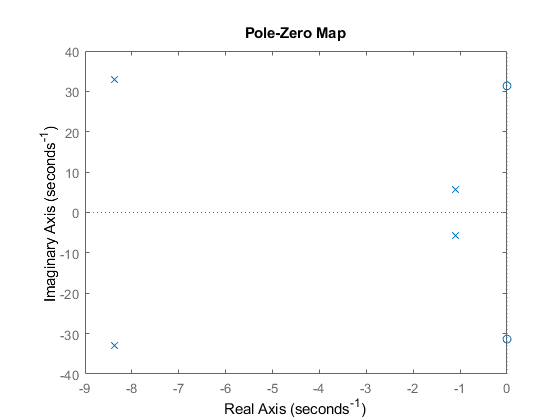

% PID Regler
pzmap(Gsu)

pole(Gsu)

ans =   -8.3611 +32.8448i
  -8.3611 -32.8448i
  -1.1056 + 5.6964i
  -1.1056 - 5.6964i


Zwei dominanten Polstellen:

- -1.1056 + 5.6964i

- -1.1056 - 5.6964i

p = (s + 1.1056 + 5.6964i)*(s + 1.1056 - 5.6964i) =  s^2 + 2.211 s + 33.67 = 33.67*(1/33.67*s^2 + 2.211/33.67*s+1)

% Regler
K_p = 1;
s = tf('s');
R_3 = K_p*33.67*(1/33.67*s^2 +  2.211/33.67*s+1)/( 2.211/33.67*s);

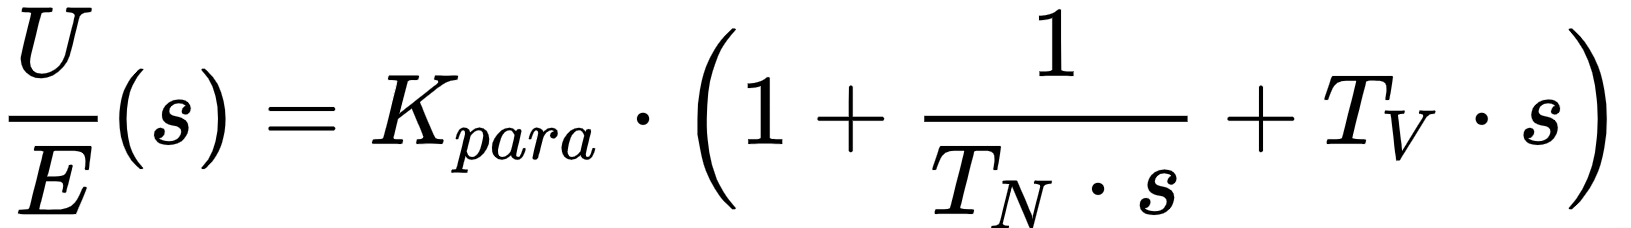

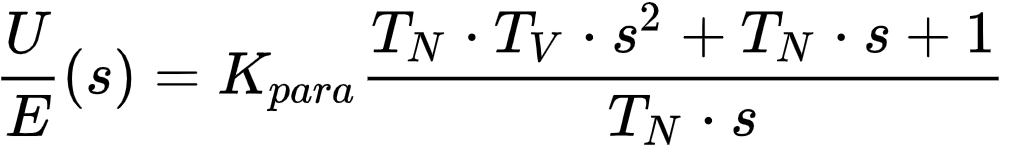

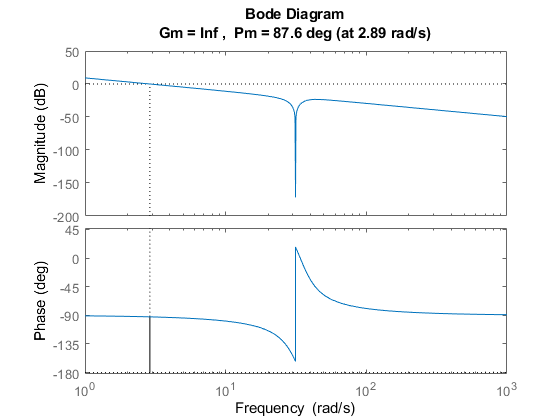

margin(Gsu*R_3)

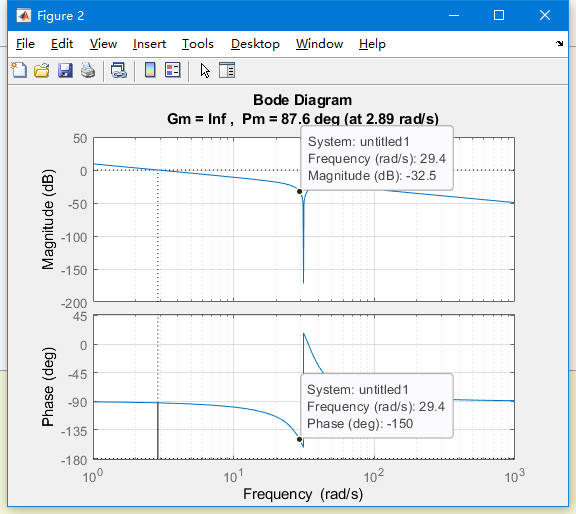

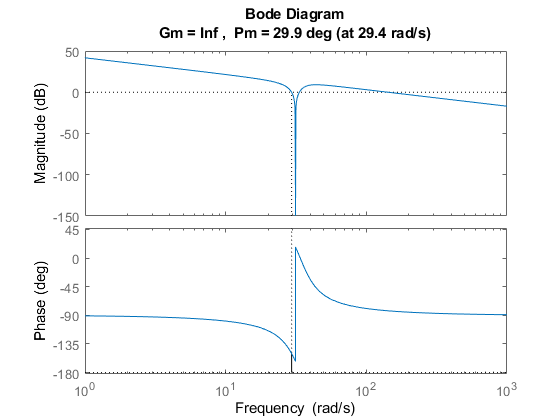

K_p = db2mag(32.5);
Gr_PID = K_p*33.67*(1/33.67*s^2 +  2.211/33.67*s+1)/( 2.211/33.67*s);
margin(Gsu*Gr_PID)

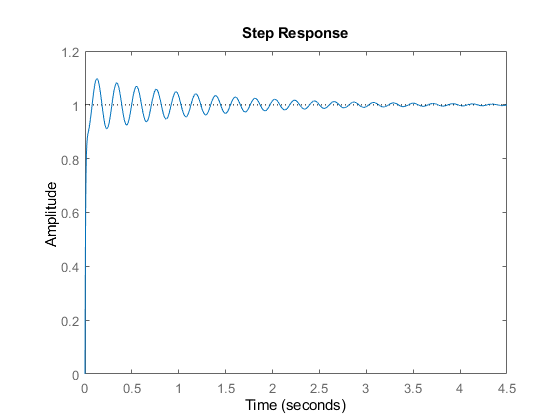

G_PID = feedback(Gsu*Gr_PID,1);
step(G_PID)

- T_N = 2.211/33.67

- T_V = 1/2.211

- K_p  = db2mag(32.5)*33.67 = 1419.8521

Mit PID-Regler: C *= *1419.8521*(1 + 1/(2.211/33.67*s) + 1/2.211*s)

- Überschwingweite: 9.69%

- Anschwingzeit: 0,0689s

- Einschwingzeit: 2,03s

- Bleibender Regelabweichung: 0

## Aufagbe 9

PID Regler mit sisotool

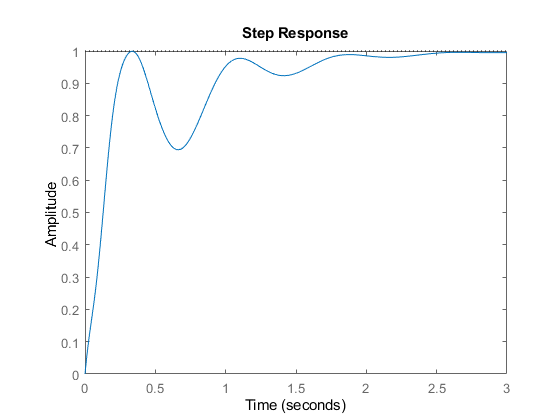

sisotool(Gsu);
R_9 = 21.028*(s+4.56)*(s+6.17)/s;
G_PID_A9 = feedback(Gsu*R_9,1);
step(G_PID_A9)

- Es gibt kaum Überschwingung

- Die Einschwingzeit ist auch klein.

- Überschwingweite: 0

- Anschwingzeit: 0,289S

- Einschwingzeit: 1,74S

- Bleibender Regelabweichung: (1-1)/1 = 0

## Aufgabe 10

R3_8 = 1419.8521*(1/33.67*s^2 +  2.211/33.67*s+1)/( 2.211/33.67*s)

R3_8 =
 
  42.17 s^2 + 93.24 s + 1420
  --------------------------
          0.06567 s
 
Continuous-time transfer function.



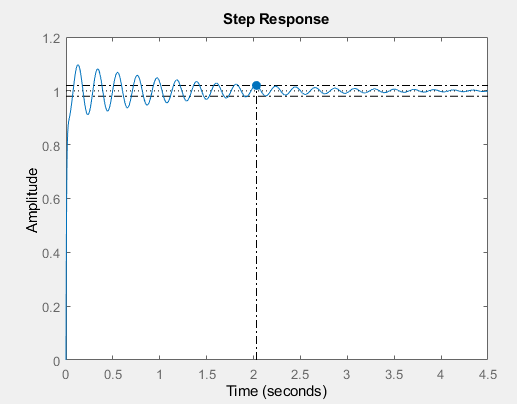

R_9 = 21.028*(s+4.56)*(s+6.17)/s

R_9 =
 
  21.03 s^2 + 225.6 s + 591.6
  ---------------------------
               s
 
Continuous-time transfer function.



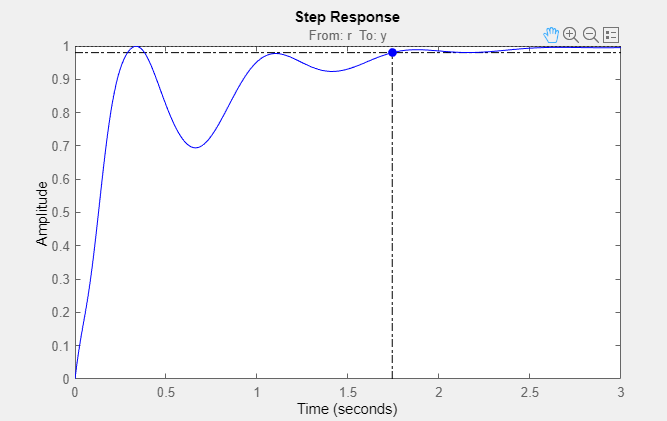

Regler

- Der Regler von Aufgabe 8 besitzt ein Paar konjugiert komplex Nullstellen.

- Der Regler von Aufgabe 9 besitzt zwei unabhängigen Nullstellen.

Sprungantwort

- Der Regler von Aufgabe 8 besitzt gleichmäßige Überschwingung und Unterschwingung.

- Der Regler von Aufgabe 9 besitzt keine Überschwingung aber eine große Unterschwingung.

- Die Einschwingzeit vom Regler von Aufgabe 9 ist kleiner als die Einschwingzeit vom Regler von Aufgabe 8.

Der Regler von Aufgabe 8

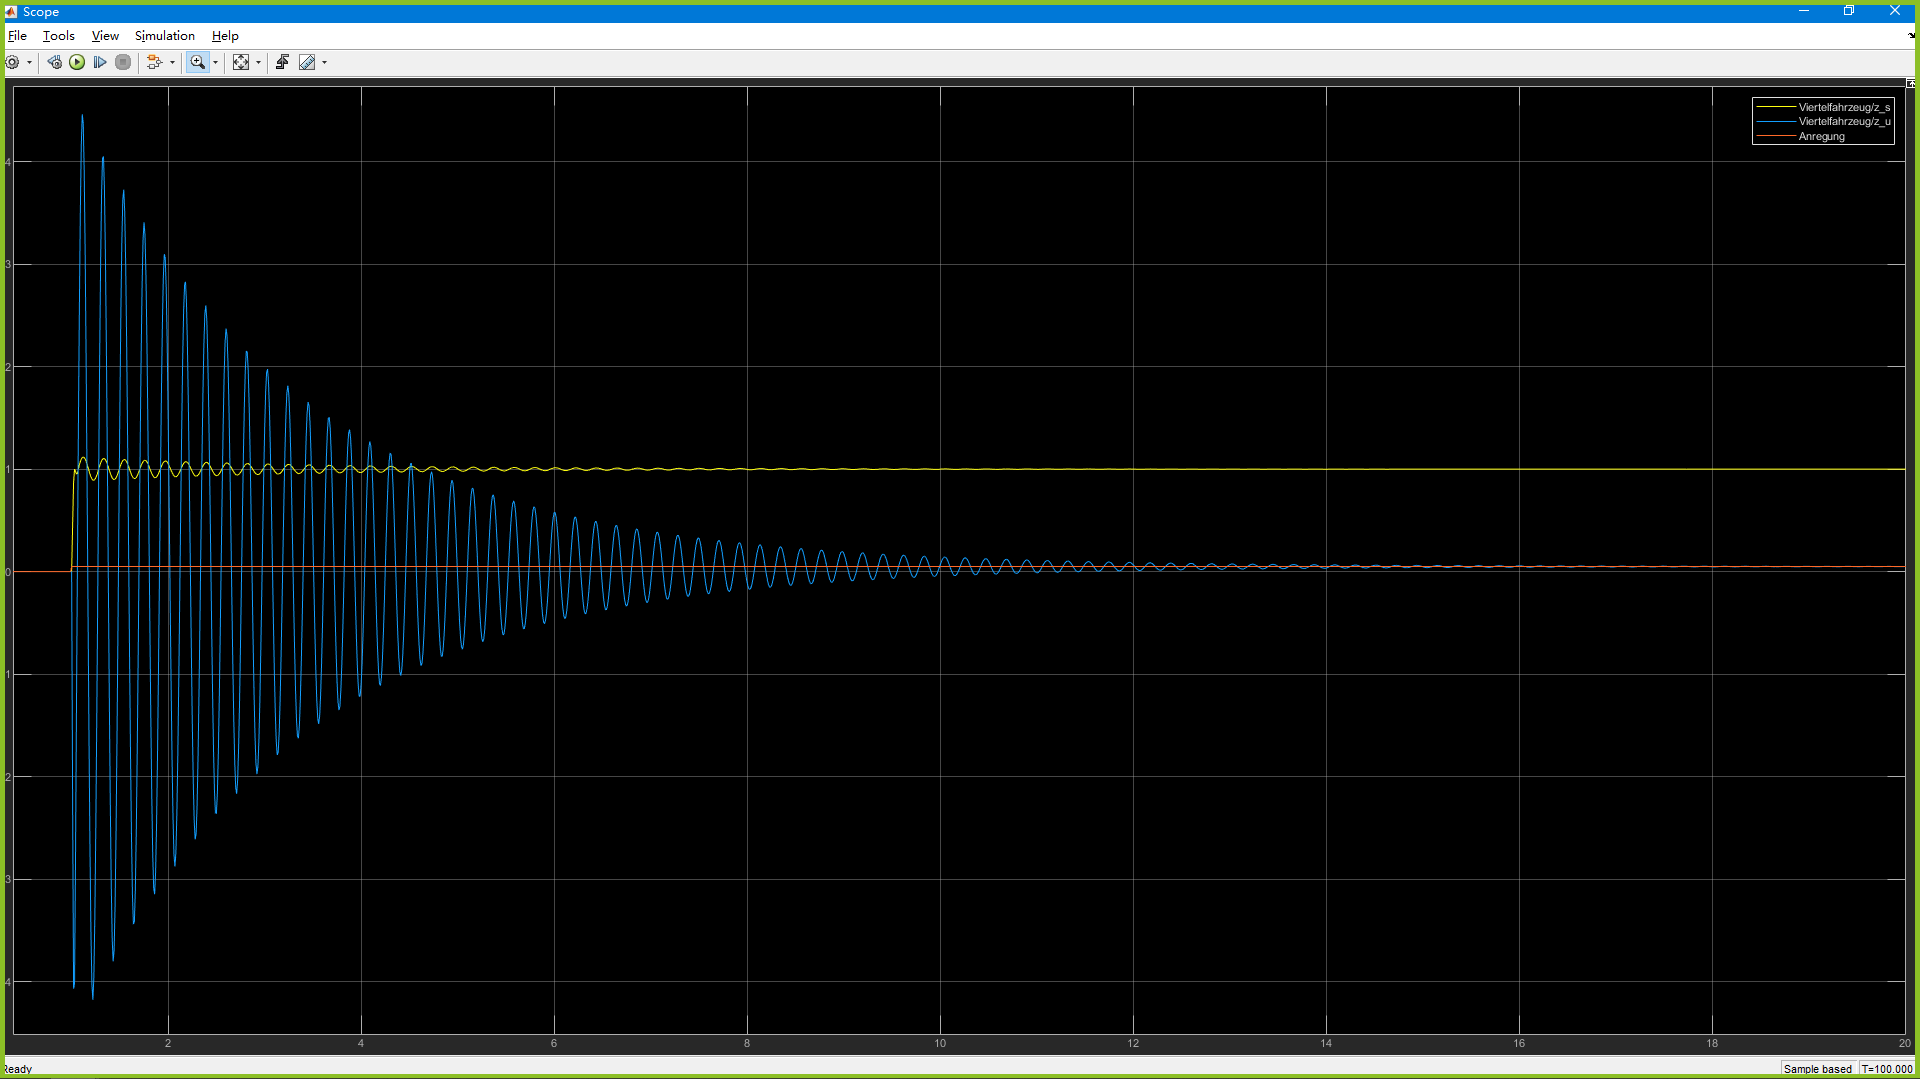

Der Regler von Aufgabe 9

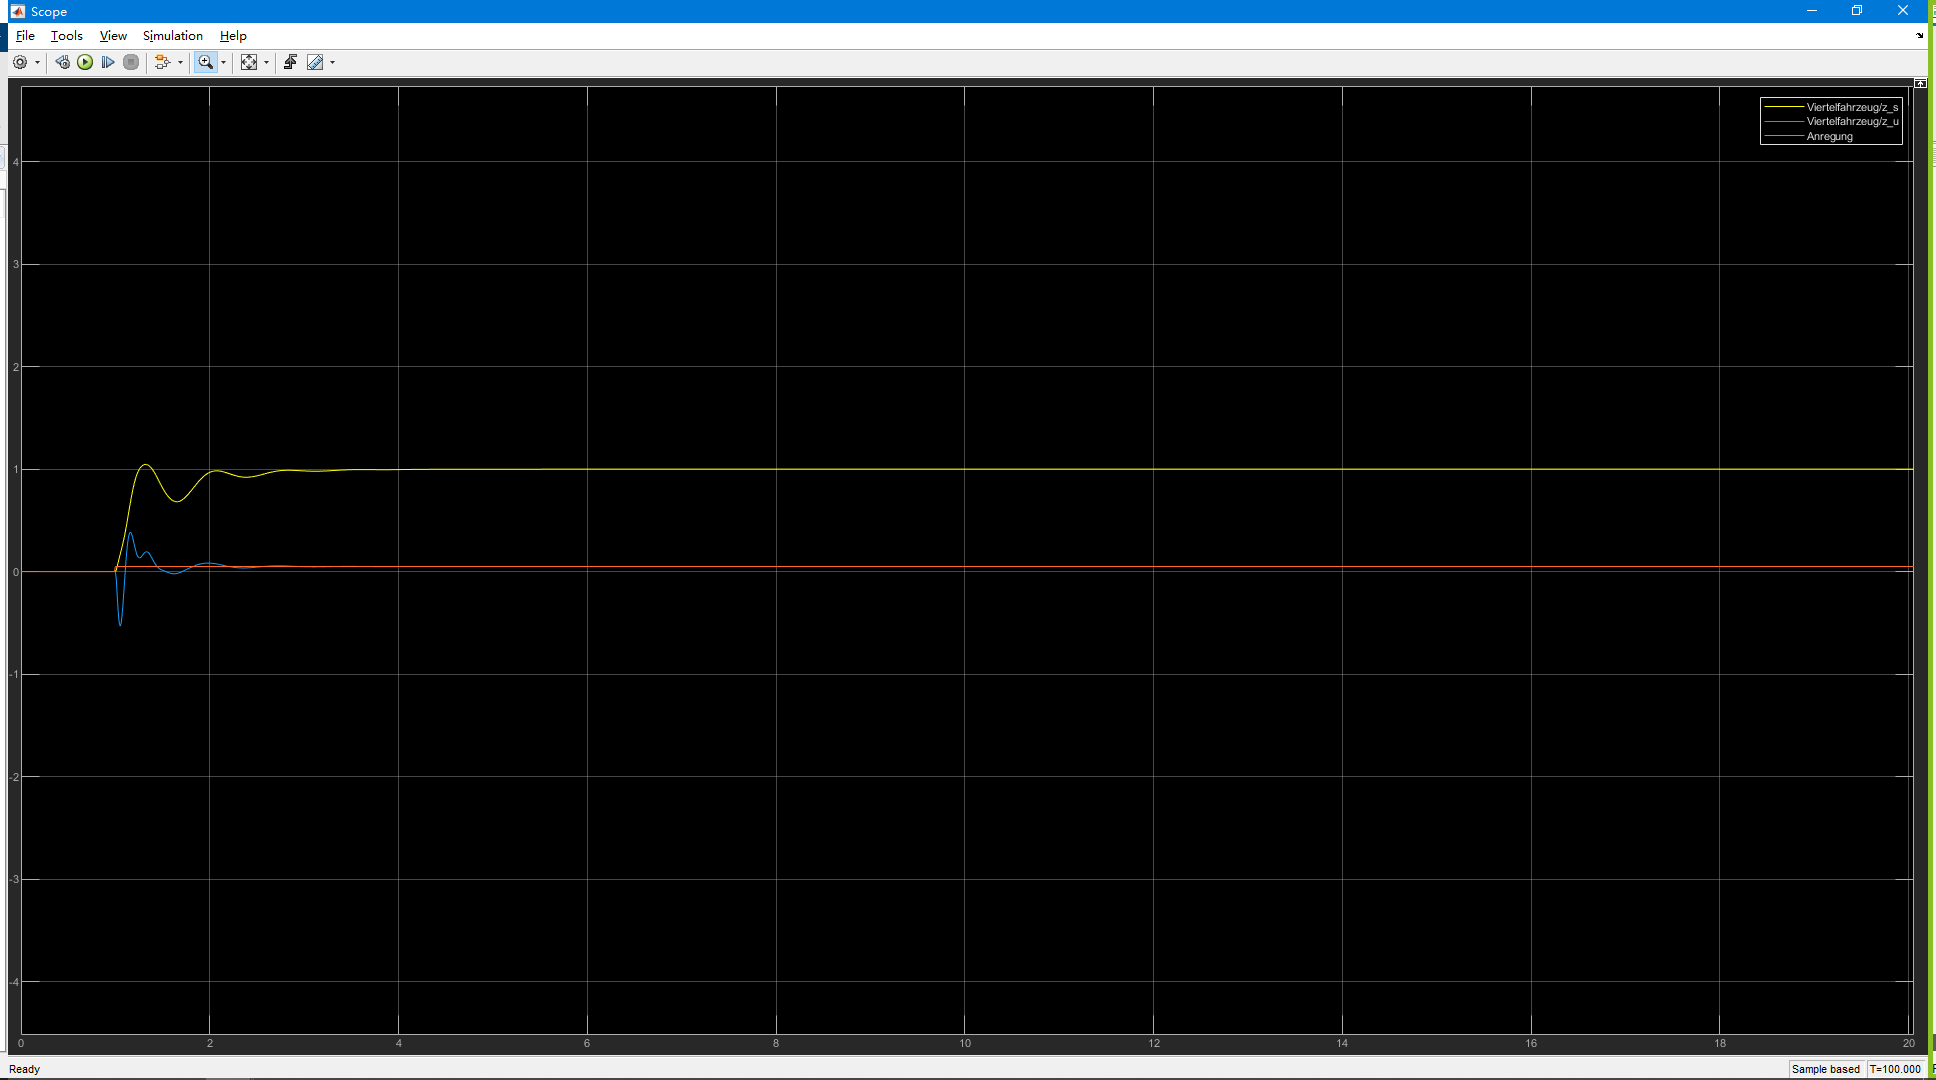

Regler 9 ist besser als Regler 8. Regler 9 wird eingesetzt.

#### Aufagbe 11

% Koeffizienten des Zählerpolynoms
b1_z = d_s*c_u;
b0_z = c_s*c_u;

% Koeffizienten des Nennerpolynoms
a4_z = m_u*m_s;
a3_z = (m_u+m_s)*d_s;
a2_z = m_s*(c_s+c_u)+m_u*c_s;
a1_z = d_s*c_u;
a0_z = c_s*c_u;

Gsz = tf([b1_z,b0_z],[a4_z,a3_z,a2_z,a1_z,a0_z]);
%--------------------------------------------
% Reglerauslegung mit dem SISO-Tool
sisotool(Gsu,1,1,Gsz);

Um die Struktur des Reglerkreises anzupassen, wird die Struktur in sisotoll abgeändert.

# Versuchsprotokoll

#### Datum: 12.05.2021

Zuerst wird das System analysiert, um die Aufgaben lösen zu können.

Dann wird ein Wirkungsplan aufgezeichnet.

Dann wird das Systemverhalten vom Regelstrecke analysiert.

Wirkungsplan aufstellen.

Modell in Simulink umzusetzen. 

Am Anfang kriegen wir eine falsche Lösung. Nach der Überprüfung werden drei Fehler erkannt.

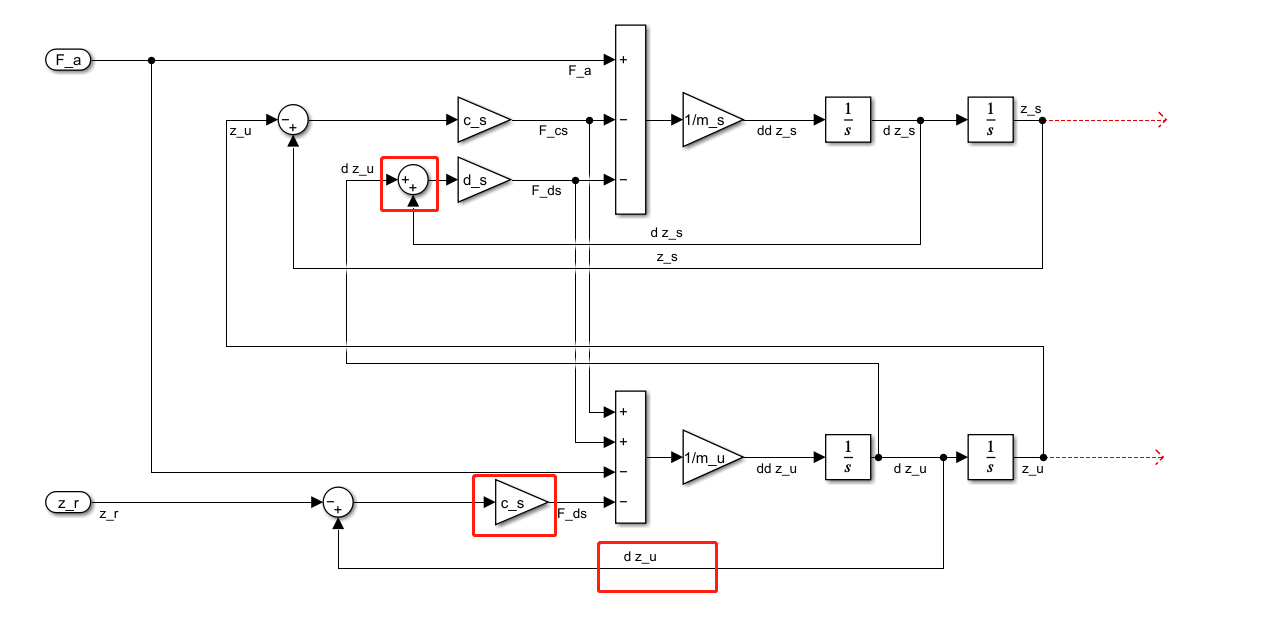

Nach der Korrektur läuft das Modell richig.

#### Datum: 12.05.2021

Aufgabe 7

Die Phasenreserve ist sehr schwierig einzustellen.

Die Regler werden in sisotool entwurfen.

Wir haben 3 Regler (P-, I- und PI-Regler ) entwurfen.

Beim I-Reegler ist es unmöglich, eine Phasenreserve von 30° zu kriegen.

offene Fragen

- Warum gibt es einen Fall im Aplitudengang? Liegt der Grund darin, dass b1_u 0 ist?

                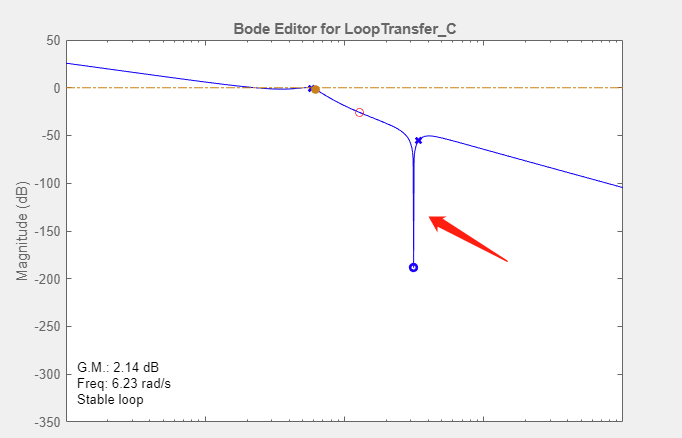

#### Datum: 14.05.2021

Aufgabe 8

Es gibt 4 Polstellen. Die zwei rechte liegenden Polstellen sollen kompensiert werden.

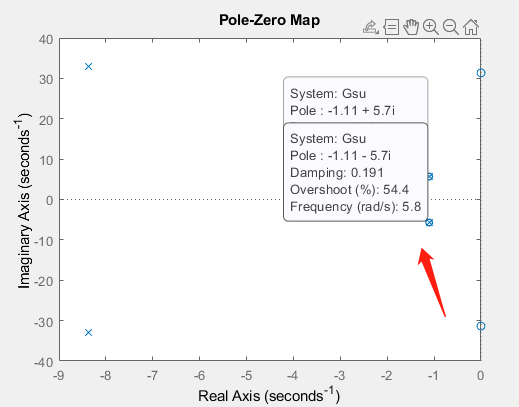

Die Gleichung wird normiert.

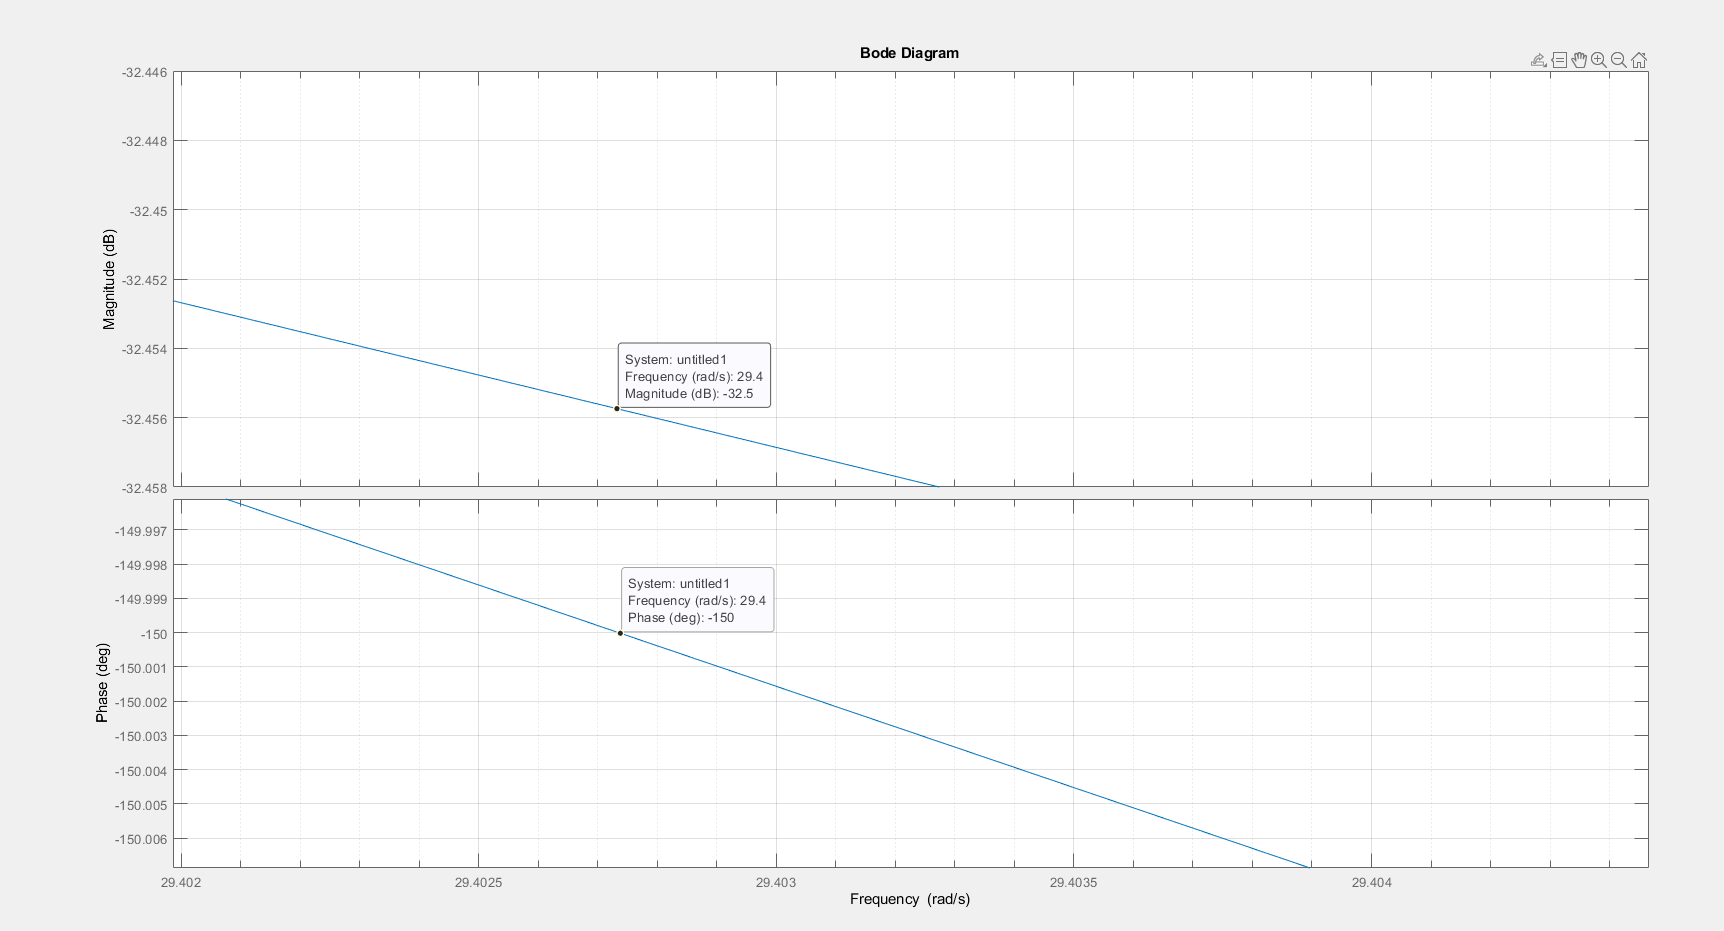

Der Betrag soll vergrößert werden.

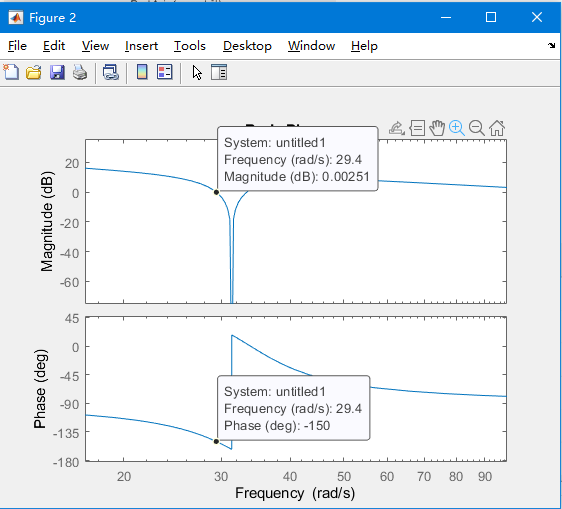

Die Phasenreserve wird richtig eingestellt.

Aufagbe 9

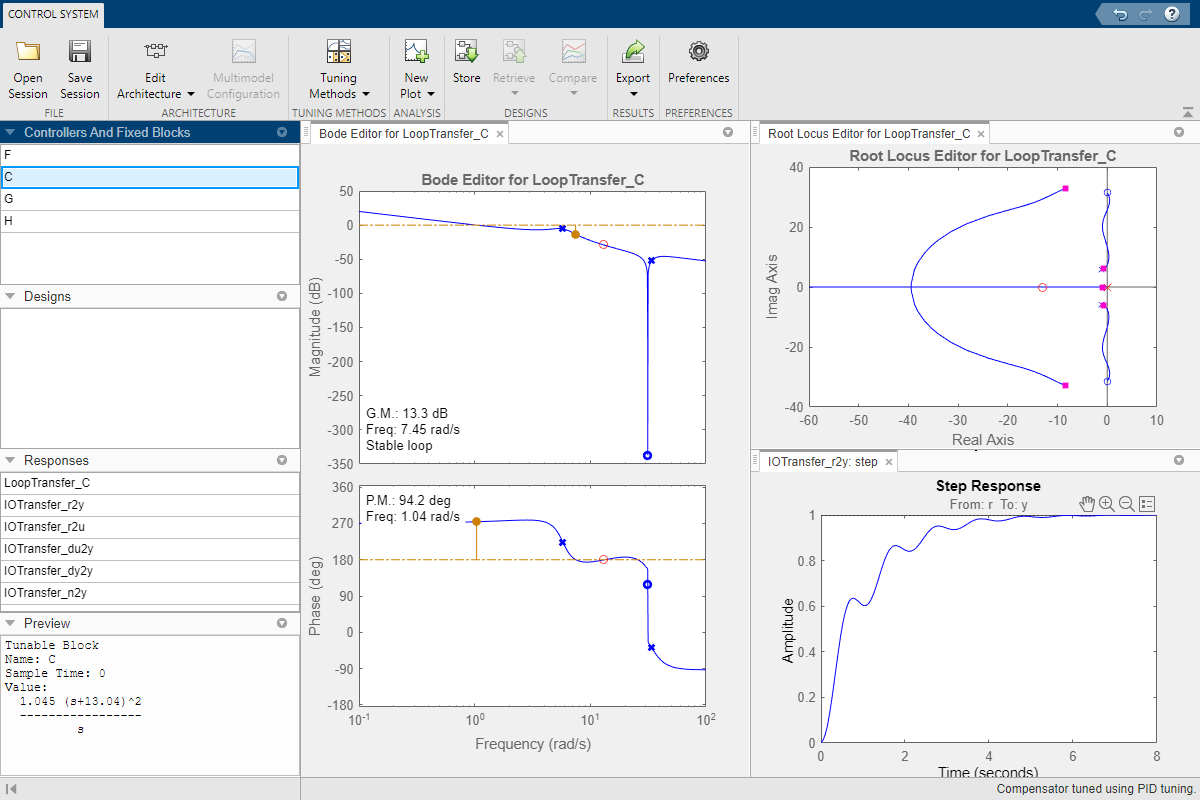

Das Modell wird in sisotool verarbeitet.

Aufagbe 11

Wir haben ein Problem getroffen.